n = 5;
x = linspace(-2,2,n);
dx = x(2) - x(1);

A = zeros(n);
b = zeros(n,1);

for i = 2:n
    A(i,i) = exp(x(i))/dx;
    A(i,i-1) = -exp(x(i))/dx;
    b(i) = 4 + sin(x(i));
end

A(1,1) = 1;
b(1) = 1;

[A b]

ans =     1.0000         0         0         0         0    1.0000
   -0.3679    0.3679         0         0         0    3.1585
         0   -1.0000    1.0000         0         0    4.0000
         0         0   -2.7183    2.7183         0    4.8415
         0         0         0   -7.3891    7.3891    4.9093


A \ b

ans =     1.0000
    9.5858
   13.5858
   15.3668
   16.0313


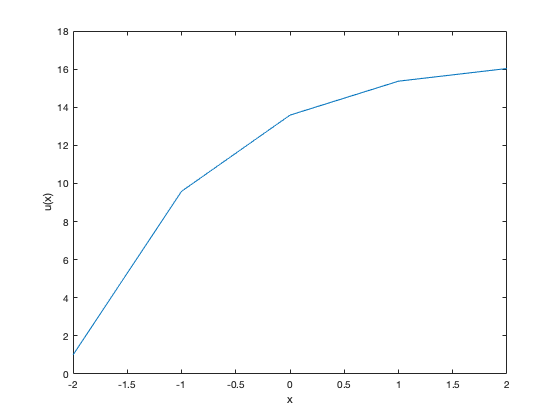

plot(x, A\b)
xlabel('x')
ylabel('u(x)')